%%Cчитаем метрики для входных данных
rootttf ='C:\Users\Lyriss\Desktop\nwhales\output3\';
stats=zeros(81,5);
a=1;
for i=1:1:81
filename= sprintf('chunk%d.wav',i);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
stats(a,1)=rms(audio1); %RMS
stats(a,2)=max(audio1)/stats(a,1); %crest factor
stats(a,3)=stats(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
stats(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
stats(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
end
s=('InputData');
disp(s);

InputData


mean_values = mean(stats);
disp(mean_values);

    0.0543    5.7048    1.6820    9.6390    0.1736



max_values=max(stats);
disp(max_values);

    0.0884    8.1611    1.9513   14.6695    0.2239



min_values=min(stats);
disp(min_values);

    0.0264    3.7764    1.4590    5.5098    0.0963



%%Считаем метрики для классических подходов аугментации
rootttf ='C:\Users\Lyriss\Desktop\nwhales\SILLY\';
statsSil=zeros(6561,5);
a=1;
for i=1:1:81
    for n=1:1:81
filename= sprintf('silly_chunk_%d_%d.wav',i,n);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsSil(a,1)=rms(audio1); %RMS
statsSil(a,2)=max(audio1)/statsSil(a,1); %crest factor
statsSil(a,3)=statsSil(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsSil(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsSil(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
    end
end
s=('Classic augmentation approach');
disp(s);

Classic augmentation approach


mean_values = mean(statsSil);
disp(mean_values);

    0.0522    5.7844    1.7431   10.1507    0.1838



max_values=max(statsSil);
disp(max_values);

    0.1249   10.2638    2.5821   26.5018    0.3233



min_values=min(statsSil);
disp(min_values);

    0.0135    3.2763    1.4590    5.3185    0.0761



%%Считаем метрики для Микширования по частоте 
rootttf ='C:\Users\Lyriss\Desktop\nwhales\VERT\';
statsVert=zeros(6165,5);
a=1;
for i=1:1:81
    for n=1:1:81
filename= sprintf('vert_chunk_%d_%d_IS.wav',i,n);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsVert(a,1)=rms(audio1); %RMS
statsVert(a,2)=max(audio1)/statsVert(a,1); %crest factor
statsVert(a,3)=statsVert(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsVert(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsVert(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
    end
end
s=('Mixing/freq');
disp(s);

Mixing/freq


mean_values = mean(statsVert);
disp(mean_values);

    0.0459    9.0402    1.7778   16.4973    0.1744



max_values=max(statsVert);
disp(max_values);

    0.0911   28.8993    3.3611   68.8217    0.2278



min_values=min(statsVert);
disp(min_values);

    0.0228    1.5616    1.4583    4.1847    0.0819



%%Считаем метрики для микширования по времени
rootttf ='C:\Users\Lyriss\Desktop\nwhales\CROPS\';
statsCrops=zeros(6165,5);
a=1;
for i=1:1:81
    for n=1:1:81
filename= sprintf('new_chunk_%d_%d.wav',i,n);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsCrops(a,1)=rms(audio1); %RMS
statsCrops(a,2)=max(audio1)/statsCrops(a,1); %crest factor
statsCrops(a,3)=statsCrops(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsCrops(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsCrops(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
    end
end
s=('Mixing/time');
disp(s);

Mixing/time


mean_values = mean(statsCrops);
disp(mean_values);

    0.0554    5.7537    1.6922    9.7607    0.1745



max_values=max(statsCrops);
disp(max_values);

    0.0979    9.6605    2.0590   18.0953    0.2351



min_values=min(statsCrops);
disp(min_values);

    0.0264    3.7764    1.4235    5.5098    0.0729



%%Считаем метрики для генерации с классическими методами
rootttf ='C:\Users\Lyriss\Desktop\nwhales\WAVEGAN\gen-classicFA\';
statsGC=zeros(100,5);
a=1;
for i=0:1:99
filename= sprintf('%dFA.wav',i);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsGC(a,1)=rms(audio1); %RMS
statsGC(a,2)=max(audio1)/statsGC(a,1); %crest factor
statsGC(a,3)=statsGC(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsGC(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsGC(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
end
s=('Generated/classic');
disp(s);

Generated/classic


mean_values = mean(statsGC);
disp(mean_values);

    0.1589    5.3400    1.8463    9.9450    0.2071



max_values=max(statsGC);
disp(max_values);

    0.3108    7.1607    2.3027   16.1552    0.2314



min_values=min(statsGC);
disp(min_values);

    0.0819    3.0794    1.4210    4.3758    0.1617



%%Считаем метрики для геренации с микшированием по частоте
rootttf ='C:\Users\Lyriss\Desktop\nwhales\WAVEGAN\gen-freqFA\';
statsGF=zeros(100,5);
a=1;
for i=0:1:99
filename= sprintf('%dFA.wav',i);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsGF(a,1)=rms(audio1); %RMS
statsGF(a,2)=max(audio1)/statsGF(a,1); %crest factor
statsGF(a,3)=statsGF(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsGF(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsGF(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
end
s=('Generated/mixFreq');
disp(s);

Generated/mixFreq


mean_values = mean(statsGF);
disp(mean_values);

    0.1014    6.3401    1.8546   11.9535    0.2260



max_values=max(statsGF);
disp(max_values);

    0.1972   12.8202    2.5007   30.4024    0.2477



min_values=min(statsGF);
disp(min_values);

    0.0177    4.4210    1.6711    7.5198    0.2033



%%Считаем метрики для генерации с микшированием по времени 
rootttf ='C:\Users\Lyriss\Desktop\nwhales\WAVEGAN\gen-timeFA\';
statsGT=zeros(100,5);
a=1;
for i=0:1:99
filename= sprintf('%dFA.wav',i);
fullname = strcat(rootttf, filename);
[audio1, fs1] = audioread(fullname);
statsGT(a,1)=rms(audio1); %RMS
statsGT(a,2)=max(audio1)/statsGT(a,1); %crest factor
statsGT(a,3)=statsGT(a,1)/(sum(abs(audio1))/length(audio1)); %shape factor
statsGT(a,4)=max(audio1)/(sum(abs(audio1))/length(audio1)); %impulse factor
statsGT(a,5)=zerocrossrate(audio1); %zero cross rate
a=a+1;
end
s=('Generated/mixTime');
disp(s);

Generated/mixTime


mean_values = mean(statsGT);
disp(mean_values);

    0.1464    5.3474    1.8058    9.6886    0.2165



max_values=max(statsGT);
disp(max_values);

    0.2364    7.1290    2.0075   14.0893    0.2345



min_values=min(statsGT);
disp(min_values);

    0.0811    3.9968    1.6766    6.8739    0.1714



%%Формируем новые массивы данных для боксплота

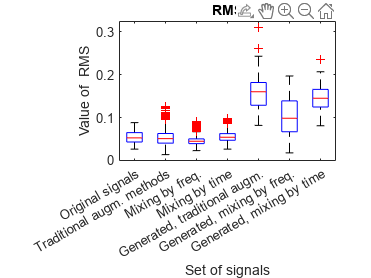

%боксплот рмс
RMS_Input = stats(:, 1);
RMS_Sil = statsSil(:, 1);
RMS_Vert = statsVert(:, 1);
RMS_Crops = statsCrops(:, 1);
RMS_GC = statsGC(:, 1);
RMS_GF = statsGF(:, 1);
RMS_GT = statsGT(:, 1);

combinedRMS=[RMS_Input;RMS_Sil;RMS_Vert;RMS_Crops;
    RMS_GC;RMS_GF;RMS_GT];

g1 = repmat({'Original signals'},81,1);
g2 = repmat({'Traditional augm. methods'},6561,1);
g3 = repmat({'Mixing by freq.'},6561,1);
g4 = repmat({'Mixing by time'},6561,1);
g5 = repmat({'Generated, traditional augm.'},100,1);
g6 = repmat({'Generated, mixing by freq.'},100,1);
g7 = repmat({'Generated, mixing by time'},100,1);
g = [g1; g2; g3; g4; g5; g6; g7];

boxplot(combinedRMS, g)
title('RMS');
xlabel('Set of signals');
ylabel('Value of  RMS');

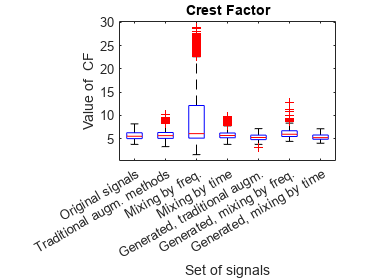

%боксплот cf
CF_Input = stats(:, 2);
CF_Sil = statsSil(:, 2);
CF_Vert = statsVert(:, 2);
CF_Crops = statsCrops(:, 2);
CF_GC = statsGC(:, 2);
CF_GF = statsGF(:, 2);
CF_GT = statsGT(:, 2);

combinedCF=[CF_Input;CF_Sil;CF_Vert;CF_Crops;
    CF_GC;CF_GF;CF_GT];

boxplot(combinedCF, g)
title('Crest Factor');
xlabel('Set of signals');
ylabel('Value of  CF');

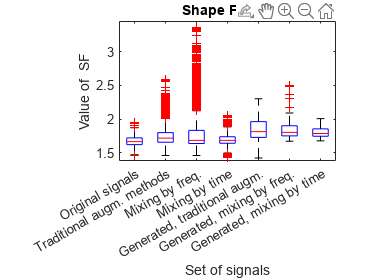

%боксплот shape factor
SF_Input = stats(:, 3);
SF_Sil = statsSil(:, 3);
SF_Vert = statsVert(:, 3);
SF_Crops = statsCrops(:, 3);
SF_GC = statsGC(:, 3);
SF_GF = statsGF(:, 3);
SF_GT = statsGT(:, 3);

combinedSF=[SF_Input;SF_Sil;SF_Vert;SF_Crops;
    SF_GC;SF_GF;SF_GT];

boxplot(combinedSF, g)
title('Shape Factor');
xlabel('Set of signals');
ylabel('Value of  SF');

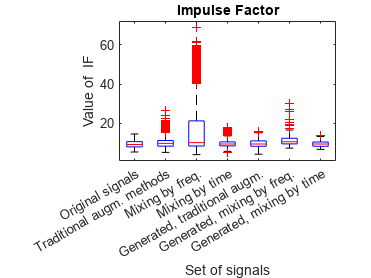

%боксплот impulse factor
IF_Input = stats(:, 4);
IF_Sil = statsSil(:, 4);
IF_Vert = statsVert(:, 4);
IF_Crops = statsCrops(:, 4);
IF_GC = statsGC(:, 4);
IF_GF = statsGF(:, 4);
IF_GT = statsGT(:, 4);

combinedIF=[IF_Input;IF_Sil;IF_Vert;IF_Crops;
    IF_GC;IF_GF;IF_GT];

boxplot(combinedIF, g)
title('Impulse Factor');
xlabel('Set of signals');
ylabel('Value of  IF');

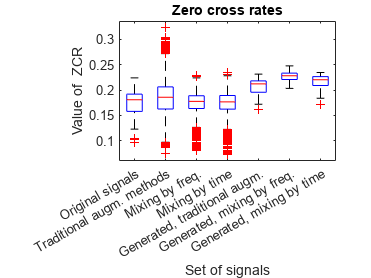

%боксплот zero cross rate
ZCR_Input = stats(:, 5);
ZCR_Sil = statsSil(:, 5);
ZCR_Vert = statsVert(:, 5);
ZCR_Crops = statsCrops(:, 5);
ZCR_GC = statsGC(:, 5);
ZCR_GF = statsGF(:, 5);
ZCR_GT = statsGT(:, 5);

combinedZCR=[ZCR_Input;ZCR_Sil;ZCR_Vert;ZCR_Crops;
    ZCR_GC;ZCR_GF;ZCR_GT];

boxplot(combinedZCR, g)
title('Zero cross rates');
xlabel('Set of signals');
ylabel('Value of  ZCR');